Demodulation(four_QAM([1 1], 1))

ans =      1     1


Convolution_code([1 1])

ans =      1     1     0     1     0     1     1     1


binVal = de2bi(0:3, 2, 'left-msb')  % path metric 계산을 위한 계산

binVal =      0     0
     0     1
     1     0
     1     1


for i = 1:4
    output0(i,:) = Convolution_code_tail_bit_X(0, binVal(i,1:2))
    output1(i,:) = Convolution_code_tail_bit_X(1, binVal(i,1:2))
end

output0 =      0     0
     1     1
     1     0
     0     1


output1 =      1     1
     0     0
     0     1
     1     0


output0 =      0     0
     1     1
     1     0
     0     1


output1 =      1     1
     0     0
     0     1
     1     0


output0 =      0     0
     1     1
     1     0
     0     1


output1 =      1     1
     0     0
     0     1
     1     0


output0 =      0     0
     1     1
     1     0
     0     1


output1 =      1     1
     0     0
     0     1
     1     0


clc
clear
close
input = randsrc(1, 200, [0 1])

input =      1     0     1     0     0     1     0     0     0     0     0     0     1     0     0     0     1     1     1     0     0     0     0     1     0     1     0     0     1     1     0     0     1     0     1     1     0     1     0     1     0     0     1     1     1     0     1     1     1     0


encoded_input = Convolution_code(input)

encoded_input =      1     1     1     0     0     0     1     0     1     1     1     1     1     0     1     1     0     0     0     0     0     0     0     0     1     1     1     0     1     1     0     0     1     1     0     1     1     0     0     1     1     1     0     0     0     0     1     1     1     0


for i = 1:length(encoded_input)/2
    modulated_output(1,2*(i-1)+1 : 2*i)=four_QAM(encoded_input(1,2*(i-1)+1 : 2*i), 40);
end
received_signal = AWGN_Channel(modulated_output,2);
for i = 1:length(modulated_output)/2
    demodulated_output(1,2*(i-1)+1 : 2*i)=Demodulation(received_signal(1,2*(i-1)+1 : 2*i));
end
decoding = Viterbi_decoding(demodulated_output, 200)

decoding =      1     0     1     0     0     1     0     0     0     0     0     0     1     0     0     0     1     1     1     0     0     0     0     1     0     1     0     0     1     1     0     0     1     0     1     1     0     1     0     1     0     0     1     1     1     0     1     1     1     0


a = nnz(input-decoding)

a = 0

% soft decision
clc
clear
close
input = randsrc(1, 10, [0 1])

input =      1     1     0     1     1     0     0     1     1     1


encoded_input = Convolution_code(input)

encoded_input =      1     1     0     1     0     1     0     0     0     1     0     1     1     1     1     1     0     1     1     0     0     1     1     1


for i = 1:length(encoded_input)/2
    modulated_output(1,2*(i-1)+1 : 2*i)=four_QAM(encoded_input(1,2*(i-1)+1 : 2*i), 20);
end
received_signal = AWGN_Channel(modulated_output,2)

received_signal =    -5.8621    2.9076   -1.7115    3.0362   -1.7328    2.7523    2.9140    6.1417   -0.3442    5.9967   -1.8193    0.7473   -1.7278    0.0982   -2.1845   -1.0929   -1.7085    2.5554    3.7500   -4.7368   -1.3855    0.8681   -5.3000   -4.7813


decoding = Viterbi_soft_decoding(received_signal, 10, 20)

decoding =      1     1     0     1     1     0     0     1     1     1


a = nnz(input-decoding)

a = 0

%awgn
clear
t = 0:pi/16:2*pi;
x = sqrt(2)*(sin(t)+ 1i *sin(t));
rng('default')
noise_v = 2

noise_v = 2

Esym=sum(abs(x).^2)/(length(x))

Esym = 1.9394

snr = Esym/(2*noise_v^2)

snr = 0.2424

rxSig = awgn(x,10*log10(snr), 'measured')

rxSig =    1.0753 - 1.6190i   3.9437 - 5.6127i  -3.9765 + 3.4180i   2.5100 + 1.4361i   1.6375 - 0.5099i  -1.4395 + 3.9165i   0.4394 - 2.1165i   2.0723 + 1.1826i   8.5710 + 0.9313i   6.9259 + 2.0255i  -1.3932 + 1.9323i   7.2457 - 0.5539i   2.4508 + 0.9399i   0.6596 + 0.4559i   1.9707 + 1.7966i  -0.1340 + 2.4624i  -0.2483 + 2.2185i   2.7035 - 2.0032i   2.2769 - 0.3865i   2.0487 - 3.2139i   0.3430 - 3.2270i  -3.5908 - 1.1896i   0.1279 + 1.7587i   1.8734 - 2.9264i  -0.4364 - 0.6715i   0.6823 - 1.8382i   0.1472 + 0.9281i  -1.7828 - 3.3540i  -0.4123 - 0.9349i  -2.3603 + 0.3194i   1.2356 + 1.6600i  -2.5700 + 2.8125i  -2.1377 + 0.1719i


rng('default')


rxSig3 = AWGN_Channel(x, noise_v)

rxSig3 =    1.0753 - 1.6190i   3.9437 - 5.6127i  -3.9765 + 3.4180i   2.5100 + 1.4361i   1.6375 - 0.5099i  -1.4395 + 3.9165i   0.4394 - 2.1165i   2.0723 + 1.1826i   8.5710 + 0.9313i   6.9259 + 2.0255i  -1.3932 + 1.9323i   7.2457 - 0.5539i   2.4508 + 0.9399i   0.6596 + 0.4559i   1.9707 + 1.7966i  -0.1340 + 2.4624i  -0.2483 + 2.2185i   2.7035 - 2.0032i   2.2769 - 0.3865i   2.0487 - 3.2139i   0.3430 - 3.2270i  -3.5908 - 1.1896i   0.1279 + 1.7587i   1.8734 - 2.9264i  -0.4364 - 0.6715i   0.6823 - 1.8382i   0.1472 + 0.9281i  -1.7828 - 3.3540i  -0.4123 - 0.9349i  -2.3603 + 0.3194i   1.2356 + 1.6600i  -2.5700 + 2.8125i  -2.1377 + 0.1719i


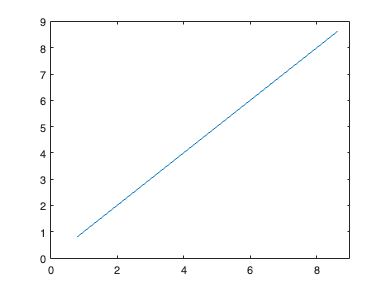

axis([0 9 0 9])

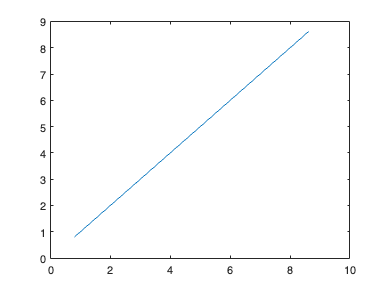

figure; plot(abs(rxSig),abs(rxSig3));